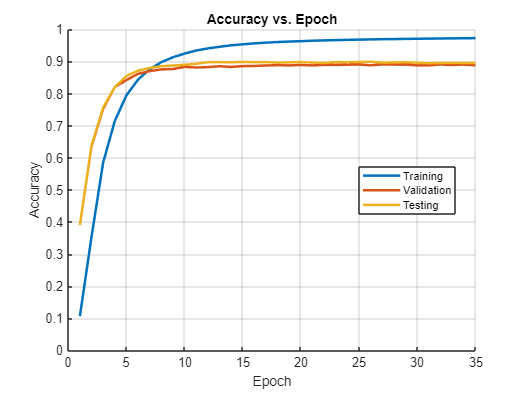

% Plot_Accuracy_Loss.mlx

% Read CSV into table
T = readtable('metrics_all.csv');

% Extract epoch and metrics
epochs     = T.epoch;
trainLoss  = T.train_loss;
valLoss    = T.val_loss;
testLoss   = T.test_loss;
trainAcc   = T.train_acc;
valAcc     = T.val_acc;
testAcc    = T.test_acc;

% Plot Accuracies vs Epoch
figure;
hold on;
plot(epochs, trainAcc, 'LineWidth', 2, 'DisplayName', 'Training');
plot(epochs, valAcc, 'LineWidth', 2, 'DisplayName', 'Validation');
plot(epochs, testAcc, 'LineWidth', 2, 'DisplayName', 'Testing');
hold off;
xlabel('Epoch');
ylabel('Accuracy');
title('Accuracy vs. Epoch');
legend('Location','best');
ylim([0 1]);
grid on;

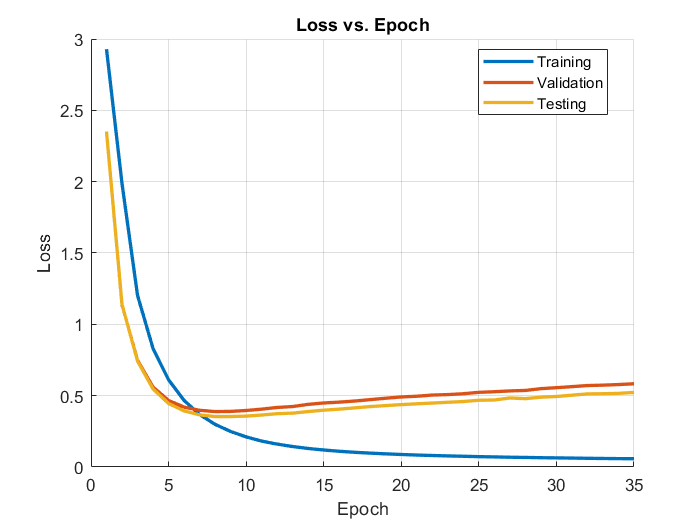


% Plot Losses vs Epoch
figure;
hold on;
plot(epochs, trainLoss, 'LineWidth', 2, 'DisplayName', 'Training');
plot(epochs, valLoss, 'LineWidth', 2, 'DisplayName', 'Validation');
plot(epochs, testLoss, 'LineWidth', 2, 'DisplayName', 'Testing');
hold off;
xlabel('Epoch');
ylabel('Loss');
title('Loss vs. Epoch');
legend('Location','best');
ylim([0 3]);
grid on;